Ejemplo de construcción y uso del gramiano de alcanzabilidad para un sistema lti

Para un sistema LTI (un par A,B) el gramiano de alcanzabilidad se define como,

$WR[t_1,0] = \int_0^{t1} e^{At}BB^Te^{A^Tt}dt$,

donde por razones (espero) conocidas estamos tomando directamente $t_0 = 0$

Podemos definir una función en matlab que calcule el integrando $ e^{At}BB^Te^{A^Tt}$para cualquier valor de t (ver la función al final de este script) e integrarla numericamente.

Vamos a ver como hacerlo con un par (A,B) de ejemplo,


$$\dot{x} =
 \pmatrix {1&2&3 \cr -2&2&1 \cr 1&4&6}\cdot \pmatrix{x_1\cr X_2 \cr X_3}+\pmatrix{1 \cr -1 \cr 2} \cdot u
$$


Construimos las matrices del sistema,

A = [1 2 3; 2 -2 1; 1 4 -6];
B = [1;-1;2];
C = rank(ctrb(A,B))

C = 3

la = eig(A)

la =     2.9176
   -3.3297
   -6.5879


El rango de la matriz de controlabilidad es e 3, por tanto, el sistema es controlable. Sin embargo, la matriz A tiene un autovalor con parte real positiva, por tanto no es una matriz de estabilidad (Kurwitz). El sistema no es estable

Supongamos que queremos obtener el $WR[0.1,0]$ (Elijo un tiempo tan corto porque, al ser un sistema inestable, diverge muy rápido. Prueba con otros sistemas estables y verás que se comporta mejor)

t1 = 0.1; %
f=@(t)dgramr(t,t1,A,B); %handle a la funcion

Tenemos dos posible maneras de integrar. La primera es usar el comando de matlab integral(f,t0,t1,'ArrayValued',1) el parámetro 'ArrayValued' hay que incluirlo y darle valor 1 para que sepa que el integrando tiene una matriz. De no hacerlo obtendremos un error.

wr10_0 = integral(f,0,t1,'ArrayValued',1)

wr10_0 =     0.1488   -0.0862    0.1689
   -0.0862    0.0548   -0.1073
    0.1689   -0.1073    0.2099


La segunda forma es hacernos nosotros un buclecito para calcular la integral podemos hacer la implemetación que queramos. La que he puesto aquí es la más cutre posible, sumo rectangulos a lo burro (menos preciso y probablemente más lento)

dt = 0.00001; %paso de integración
t = 0:dt:t1;
WR10_0 = 0;
for i =1:length(t)
WR10_0 = WR10_0 + dgramr(t(i),t1,A,B)*dt;
end
WR10_0

WR10_0 =     0.1488   -0.0862    0.1689
   -0.0862    0.0548   -0.1073
    0.1689   -0.1073    0.2099


diferencia = wr10_0 - WR10_0

diferencia = 1.0e-04 *

   -0.1483    0.0830   -0.1687
    0.0830   -0.0611    0.1231
   -0.1687    0.1231   -0.2481


La diferencia es del orden del paso de integración elegido para el segundo método

Supongamos ahora que queremos en un 0.1 segundos alcanzar el estado;


$$x1= \pmatrix{1\cr 1 \cr -1}$$


Como el sistemas es controlable, $x1\in Im\{WR[0, t1]\} \Rightarrow \eta_1 = WR[0,1]^{-1}x_1$.

x1 = [1;1;-1]

x1 =      1
     1
    -1


eta1 = inv(WR10_0)*x1

eta1 = 1.0e+04 *

   -0.0096
    3.3989
    1.7443


Ahora sabemos que para llevar nuestro sistema en tiempo t1 a x1 debemos emplear una entrada:


$$u(t)=B^T\Phi(0,t_1)^T\eta_1=B^Te^{A^T(t_1-t)} \eta_1$$
 

Así que creamos una función para $u(t)$ (Ver al final del archivo)

u =@(t)U(t,t1,A,B,eta1);

Ahora deberíamos integrar nuestro sistema lineal a ver qué pasa

Podemos hacerlo de varias maneras:

- Emplear ode45. Para ello, tenemos que crear como siempre una función con el sistema lineal (ver al final del fichero)

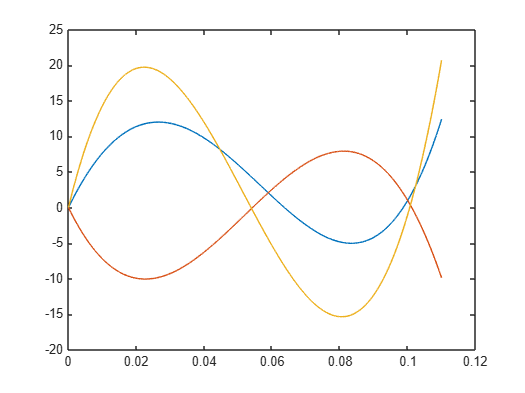

sys = @(t,x)sistema_lineal(t,x,u,A,B);
opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,t1+0.01],[0;0;0],opciones);
figure(1)
plot(t,x)

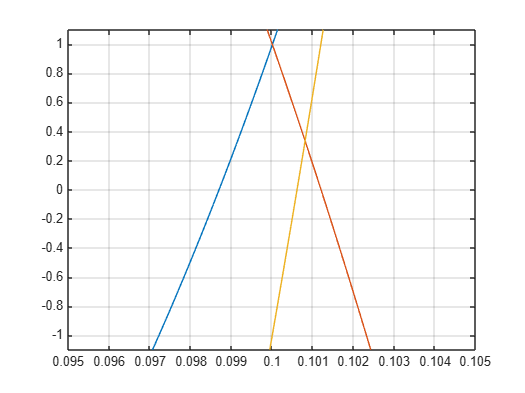

figure(2)
plot(t,x)
axis([0.095 0.105 -1.1 1.1])
grid

Hacemos zoom en torno a 0.1 para comprobar que. efectivamente, para ese punto se han alcanzado los valores deseados

2. los sistemas lineales en matlab admiten una construcción especial, 

Podemos emplearla pero, hay que definir las 4 matrices A,B,C,D típicas de cualquier sistema lineal

C = eye(3); %considero todos los estados como salidas del sistema
D = 0

D = 0

sys = ss(A,B,C,D)


sys =
 
  A = 
       x1  x2  x3
   x1   1   2   3
   x2   2  -2   1
   x3   1   4  -6
 
  B = 
       u1
   x1   1
   x2  -1
   x3   2
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


Para poder simular la entrada debemos calcularla específicamente para un array de tiempos

t1 = 0.1

t1 = 0.1000

t = 0:0.001:t1;
for i =1:length(t)
Ut(i) = U(t(i),t1,A,B,eta1);
end

Empleamos ahora el comando lsim de matlab para obtener la evolución de los estados a lo largo del tiempo. Damos una condición inicial $x_0$. En este caso, en el que $x_0=0$, se puede omitir completamente en la llamada a lsim

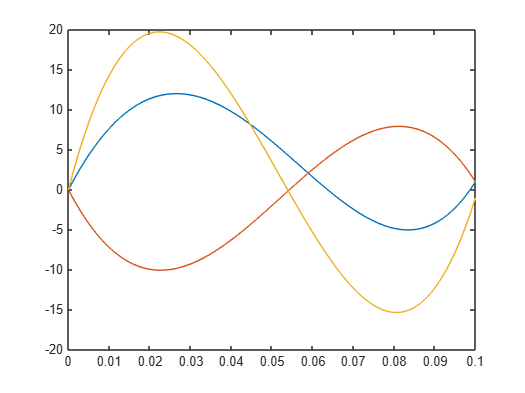

x0 = [0;0;0];
[y,t,x] = lsim(sys,Ut,t,x0);
figure()
plot(t,x)

Notas finales. Es interesante observar que, mientras que el gramiano de alcanzabilidad, nos proporciona un sistema para calcular una entrada $u$ que lleve el sistema a cualquier punto del espacio de estados. La matriz de comtrolabilidad no lo permite directamente, ni siquiera en este caso que la matriz de controlabilidad es invertible.

function  dwr= dgramr(t,t1,A,B)
%esta función permite construir el valor del integrando del grammiano de
%alcanzabilidad para un par A,B y un tiempo final t1,tiempo inicial t0=0
%si creamos un handle f = @(t)gramr(t,t1,A,B) in lo pasamos a la funcion de
%matlab integral, obtenemos el valor de gramiano Wr(t1,0)
dwr = expm(A*(t1-t))*B*B'*expm(A'*(t1-t));
end
function s = U(t,t1,A,B,eta)
%función para obtener la entrada de control de mínima energía que lleva un
%sistema LTI de x0 = 0 a X1. eta, de debe obtenerse a partir de x1 calculando
%e invirtiendo el gramiano de alcanzabilidad
s = B'*expm(A'*(t1-t))*eta;
end
function xdot = sistema_lineal(t,x,u,A,B)
xdot = A*x+B*u(t);
end